# **Hourly energy demand generation and weather**

Este dataset contiene cuatro años de información de demanda eléctrica de España. En al documentación se puede apreciar como el archivo:

- `energy_dataset.csv`: incluye 35 064 registros (fila por hora) y 29 columnas.

energy_demand = readtable('data\hourly_energy_demand\energy_dataset.csv', 'Delimiter', ',', 'VariableNamingRule', 'preserve');

Como atributos se tiene la **producción eléctrica por tipo de fuente** (biomasa, diferentes categorías de combustibles fósiles, varias tecnologías hidroeléctricas, nuclear, solar, eólica, residuos, etc.), las **cargas totales previstas y reales**, y, los **precios de la electricidad**.

energy_column = energy_demand.Properties.VariableNames';

Luego se tiene un segundo archivo:

- `weather_features.csv`: incluye 178 369 observaciones y 17 variables meteorológicas como temperatura, presión y humedad.

% weather_state = readtable('data\hourly_energy_demand\weather_features.csv', 'Delimiter', ',', 'VariableNamingRule', 'preserve');
% weather_column = weather_state.Properties.VariableNames';

Sin embargo, y por efectos de tiempo, el análisis se centró en las variables energéticas debido a que se tiene un mayor entendimiento que a las condiciones atmosféricas.

## Preprocesado de datos

#### Limpieza de tiempo y rasgos temporales

% Cambia de string a formato datatime
energy_demand.time = datetime(energy_demand.time, 'InputFormat','yyyy-MM-dd HH:mm:ssXXX', 'TimeZone','UTC')

energy_demand = 35064×29 table
            time            generation biomass    generation fossil brown coal/lignite    generation fossil coal-derived gas    generation fossil gas    generation fossil hard coal    generation fossil oil    generation fossil oil shale    generation fossil peat    generation geothermal    generation hydro pumped storage aggregated    generation hydro pumped storage consumption    generation hydro run-of-river and poundage    generation hydro water reservoir    generation marine    generation nuclear    generation other    generation other renewable    generation solar    generation waste    generation wind offsho


% Tabla de características agregadas. Preprocesamiento
energy_feat = table();

% Rasgos temporales
t  = energy_demand.time;
energy_feat.time = t;
energy_feat.hour = hour(t);
energy_feat.dayofweek = mod(weekday(t) + 5, 7);
energy_feat.month = month(t);

#### Selección y agregación de variables energéticas

% Helper: suma segura de columnas existentes
sumCols = @(T, cols) sum(T{:, intersect(cols, T.Properties.VariableNames, 'stable')}, 2, 'omitnan');

% Variables sumadas
energy_feat.generation_fossil_fuel = sumCols(energy_demand, energy_column(3:9));
energy_feat.generation_hydro = sumCols(energy_demand, energy_column(11:14));
energy_feat.generation_wind_total = sumCols(energy_demand, energy_column(21:22));

% Variables individuales
energy_feat.generation_solar = energy_demand.("generation solar");
energy_feat.generation_nuclear = energy_demand.("generation nuclear");

% Cargas y precios
energy_feat.total_load_actual = energy_demand.("total load actual");
energy_feat.total_load_forecast = energy_demand.("total load forecast");
energy_feat.price_day_ahead = energy_demand.("price day ahead");
energy_feat.price_actual = energy_demand.("price actual");

#### Tabla preprocesada

energy_feat

energy_feat = 35064×13 table
            time            hour    dayofweek    month    generation_fossil_fuel    generation_hydro    generation_wind_total    generation_solar    generation_nuclear    total_load_actual    total_load_forecast    price_day_ahead    price_actual
    ____________________    ____    _________    _____    ______________________    ________________    _____________________    ________________    __________________    _________________    ___________________    _______________    ____________

    31-Dec-2014 23:00:00     23   

# **K-Means**

#### Determinación de atributos de interes

% Suponiendo que 'data' es una tabla o matriz con las variables seleccionadas
X = table2array(energy_feat(:, ["hour" "generation_fossil_fuel"]));              % Convertir tabla a matriz
X = zscore(X)                       % Normalizar

X =     1.6613   -0.1175
   -1.6613   -0.0463
   -1.5168   -0.1778
   -1.3724   -0.4461
   -1.2279   -0.5845
   -1.0835   -0.6734
   -0.9390   -0.7301
   -0.7945   -0.7727
   -0.6501   -0.7334
   -0.5056   -0.6856



K = 3;                              % número de clústeres
opts = statset('Display','final');  % mostrar convergencia

% Ajustar K‑means (varias réplicas mejoran estabilidad)
[idx, C, sumd] = kmeans(X, K, 'Replicates', 10, 'Options', opts);

Replicate 1, 31 iterations, total sum of distances = 25012.4.
Replicate 2, 23 iterations, total sum of distances = 25012.4.
Replicate 3, 28 iterations, total sum of distances = 25012.4.
Replicate 4, 36 iterations, total sum of distances = 25012.4.
Replicate 5, 27 iterations, total sum of distances = 25012.4.
Replicate 6, 33 iterations, total sum of distances = 25012.4.
Replicate 7, 21 iterations, total sum of distances = 25012.4.
Replicate 8, 32 iterations, total sum of distances = 25012.4.
Replicate 9, 21 iterations, total sum of distances = 25012.4.
Replicate 10, 28 iterations, total sum of distances = 25012.4.
Best total sum of distances = 25012.4



% Evaluación del número de clústeres: método del codo
maxK = 8;
wcss = zeros(maxK,1);
for k = 1:maxK
    [~, ~, sumd_k] = kmeans(X, k, 'Replicates', 5);
    wcss(k) = sum(sumd_k);
end

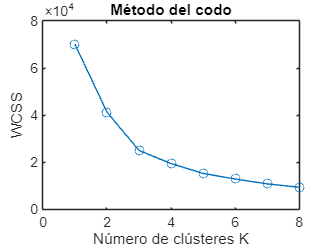

plot(1:maxK, wcss, '-o');
xlabel('Número de clústeres K'); ylabel('WCSS'); title('Método del codo');


% Evaluación con silhouette
silh = silhouette(X, idx);
meanSilh = mean(silh);
fprintf('Silhouette medio = %.3f\n', meanSilh);

Silhouette medio = 0.587
